# Advanced Research Drying Apparatus

# System Analysis Document

System Developer:                 Forest Concepts, LLC

Primary Engineering Staff:     Dr. Jim Dooley, PhD, Project Lead

                                                Christopher Lanning, Design Engineer

                                                Christopher McKiernan, Mechanical Engineer

                                                David Meissner, Mechanical Engineer

## Overview

The United States Department of Agriculture (USDA) listed Small Business Innovation Research (SBIR) Program Phase II included an objective to promote the use of biofuels and non-food biobased products by developing new or improved technologies that will lead to increased production of biofuels, industrial chemicals, and other value-added products from agricultural materials. More specifically, USDA Research Priorities include Agriculturally-related Manufacturing Technology and Alternative and Renewable Energy. 

Forest Concepts, LLC submitted a proposal to address these priorities and to address the risks, primarily related to cost, of drying within the solid and liquid biofuels industry. Through the design and development of an Advanced Research Drying Apparatus (aRDA) research questions will be addressed and reveal practical solutions to reducing less effective and costly industry methods. A preliminary view of the aRDA is shown in Figure 1: Draft System CAD Overview.

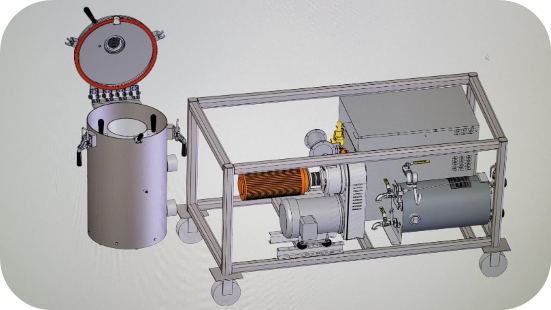

Figure 1: Draft System CAD Overview

## Variables

Notation used for variables in mathematical expressions are shown on the left. "MATLAB variable" names are shown in parentheses.

    $m_a =$ mass of dry air (`m_a`)

    $m_v =$ mass of vapor (`m_v`)

    $M_{\textrm{air}} =$ molecular weight of dry air, $\frac{\textrm{kg}}{\textrm{mol}}$

    $M_{\textrm{vapor}} =$ molecular weight of water vapor (moist air), $\frac{\textrm{kg}}{\textrm{mol}}$

    $n_a =$ Number of moles of dry air (`n_a`)

    $n_v =$ Number of moles of water vapor (`n_v`)

    $P_g =$ Pressure of air/vapor mixture, $\textrm{kPa}$ (`P_g`)

    $P_t =$ Pressure (or total pressure), $\textrm{kPa}$ (`P_t`)

    $P_s =$ Saturation vapor pressure, $\textrm{kPa}$ (`P_s`)

    $P_v =$ Vapor ressure, $\textrm{kPa}$ (`P_v`)

    $\phi =$ Relative humidity (May also be written as $\textrm{RH}$.) (`phi`)

    $q=\;$Humidity ratio (`q`)

    $R=$ Ideal gas constant, $\frac{\textrm{Pa}{\;\cdot m}^2 }{K\cdot \textrm{mol}}$ (`R`)

    $R_a =$ Specific gas constant for dry air, $\frac{J}{\textrm{kg}\cdot K}$ (`R_a`)

    $R_v =$ Specific gas constant for water vapor, $\frac{J}{\textrm{kg}\cdot K}$ (`R_v`)

    $\textrm{RH}=$ Relative Humidity (May also be written as $\phi$.) (`phi`)

    $T_C =$ Temperature, $C^{\circ }$ (`T_c`)

    $T_{\textrm{dp}} =$ Dew point temperature, $C^{\circ }$ (`T_dp`)

    $T=$ temperature, $K^{\circ }$ (`T`)

    $V_a =$ Volume of dry air, $m^3$ (`V_a`)

    $V_g =$ Volume of total gas mixture, $m^3$ (`V_g`)

    $V_t =$ Total volume, $m^3$ (`V_t`)

    $V_v =$ volume of water vapor, $m^3$(`V_v`)

    $w=$ mixing ratio (or mole fraction) of water vapor to dry air, $\frac{\textrm{mol}}{\textrm{mol}}$ (`w`)

clear; close all; clc
fig = uifigure;
d = uiprogressdlg(fig, "Title", "Processing", "Message",...
    "Performing Calculations", "Cancelable","on","Indeterminate","on");
drawnow
conversion = 273.15;
temp_outside = 25 + conversion;
temp_desired = 100 + conversion;


c_a = 1.0035;       % J/K, (c_a) thermal_mass_air
c_s = 0.15;         % J/K, (c_s) thermal_mass_structure.
u_s = [0.01 0.02];  % W/(m*K), (u_s) conductance air/structure
u_a = 0.01;         % W/(m*K), (u_a) conductance structure/envelope
% q_h = 10;            % heat flux due to heater (q_h)
% q_a = 0;            % total heat flux for the air (q_a)
% q_s = 0;            % heat flux for the structure (q_s)

for i = 1:length(u_s)

## Mathematical Representation

### State-space Representation

The system is assumed to be continuous and time-invariant, and without feedthrough, thus it may be represented using state-space representation as follows


$$\begin{array}{l}
\dot{\mathit{\mathbf{x}}} \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\\
\mathit{\mathbf{y}}\left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right)
\end{array}$$


where $\mathit{\mathbf{x}}\left(t\right)$ is the time-dependent state vector, $\mathit{\mathbf{y}}\left(t\right)$ is the time-dependent output vector, $u\left(t\right)$ is the time-dependent input vector, $\mathit{\mathbf{A}}$is the state or system matrix, $\mathit{\mathbf{B}}$ is the input matrix, and $\mathit{\mathbf{C}}$ is the output matrix.

The first task required with this system is to take measurements of specific variables that will allow us to definitely calculate each of the other variables or parameters of the system. In this case, the system is designed to measure $T_a$, temperature of the air, $T_s$, temperature of the structure and $T_o$, temperature outside the structure.

The state vector, $\mathit{\mathbf{x}}$, of the system with dimensions $n\times 1$


$$\mathbf{x} = \left [ \matrix{T_a \cr T_s \cr T_o} \right ]$$


The ability to control system parameters is essential to safety and operation. In this case, the system is designed to control $Q_a$, the total heat flux for the air enclosed within the system, $Q_s$, the heat flux of the structure of the system, and $Q_h$, the heat flux of the heater. 

The input or control vector, $\mathit{\mathbf{u}}$, with dimensions $p\times 1$ is


$$\mathbf{u} = \left [ \matrix{Q_a \cr Q_{s} \cr Q_{h}} \right ]$$


The output vector, $\mathit{\mathbf{y}}$, of the system with dimensions $q\times 3$ is


$$\mathit{\mathbf{y}}=\left\lbrack \begin{array}{c}
T_a \\
T_s \\
T_o 
\end{array}\right\rbrack$$


The system matrix, $A$, has dimensions $n\times n$ and the following form.


$$\mathbf{A} = \left[ \matrix{\frac{-(U_a+U_s)}{C_a} & \frac{U_s}{C_a} & \frac{U_a}{C_a} \cr  \frac{U_s}{C_s} & \frac{-U_s}{C_s} & 0 \cr 0 & 0 & -1    } \right]$$


    A(:,:,i) = [-(u_a + u_s(i))/c_a, u_s(i)/c_a, u_a/c_a;...
        u_s(i)/c_s, -u_s(i)/c_s, 0;...
        0, 0, -1];

The input matrix, $\mathit{\mathbf{B}}$, with dimensions $n\times p$


$$\mathbf{B}=\left[\matrix{ \frac{1}{C_a} &0&0\cr 0& \frac{1}{C_s} &0\cr0&0&\frac{1}{C_s}       }\right]$$


    B = [1/c_a, 0, 0;...
        0, 1/c_s, 0;...
        0, 0, 1/c_s];

The output matrix, $\mathit{\mathbf{C}}$, has dimensions $q\times n$ is


$$\mathbf{C}=\left[\matrix{1&0&0 \cr 0&1&0 \cr 0&0&1} \right]$$


    C = eye(3);

The feedthrough matrix, $\mathit{\mathbf{D}}$, has dimensions, $n\times p$


$$\mathbf{D}=\left[\matrix{0&0&0 \cr 0&0&0 \cr 0&0&0} \right]$$


    % D is zero because there is no feedthrough
    D = 0*eye(3);

    % Define time vectorr
    sampling_frequency = 10;  % Hz
    t_final = 500;
    t = 0 :  1 / sampling_frequency : t_final;
    delta_t = t(2) - t(1);

    % Define frequency domain variable, s
    s = tf('s');

    % Initial conditions
    initial_conditions = [273.15, 283.15];

    d.Message = "Creating state-space object";
    drawnow

## System Model

The system in state-space representation is

    % Create state-space model object
    model_state_space(:,:,i) = ss(A(:,:,i),B,C,D)

model_state_space =
 
  A = 
             x1        x2        x3
   x1  -0.01993  0.009965  0.009965
   x2   0.06667  -0.06667         0
   x3         0         0        -1
 
  B = 
           u1      u2      u3
   x1  0.9965       0       0
   x2       0   6.667       0
   x3       0       0   6.667
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
Continuous-time state-space model.



model_state_space(:,:,1,1) =
 
  A = 
             x1        x2        x3
   x1  -0.01993  0.009965  0.009965
   x2   0.06667  -0.06667         0
   x3         0         0        -1
 
  B = 
           u1      u2      u3
   x1  0.9965       0       0
   x2       0   6.667       0
   x3       0       0   6.667
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 

model_state_space(:,:,2,1) =
 
  A = 
             x1        x2        x3
   x1   -0.0299   0.01993  0.009965
   x2    0.1333   -0.1333         0
   x3         0         0        -1
 
  B = 
           u1      u2      u3
   x1  0.9965       0       0
   x2       0   6.667       0
   x3       0       0   6.667
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
2x1 array of continuous-time state-space models.


    d.Message = "Tuning Closed-loop System";
    drawnow

The system respresented in frequency domain is

    G(:,:,i) = idtf(model_state_space(:,:,i),...
        'InputName', 'q', ...
        'OutputName', 'y')

G =
 
  From input "q(1)" to output...
              0.9965 s + 0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
                   0.06643
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(2)" to output...
                   0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
               6.667 s + 0.1329
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(3)" to output...
                   0.06643 s + 0.004429
   y(1):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
                         0.004429
   y(2):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
          6.667
   y(3):  -----
          s + 1
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 2 3;2 2 3;0 0 1]   Number of

G(:,:,1,1) =
 
  From input "q(1)" to output...
              0.9965 s + 0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
                   0.06643
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(2)" to output...
                   0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
               6.667 s + 0.1329
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(3)" to output...
                   0.06643 s + 0.004429
   y(1):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
                         0.004429
   y(2):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
          6.667
   y(3):  -----
          s + 1
 
  Parameterization:
     Number of poles: [2 2 3;2 2 3;0 0 1]   Number of zeros: [1 0 1;0 1 0;0 0 0]
     N

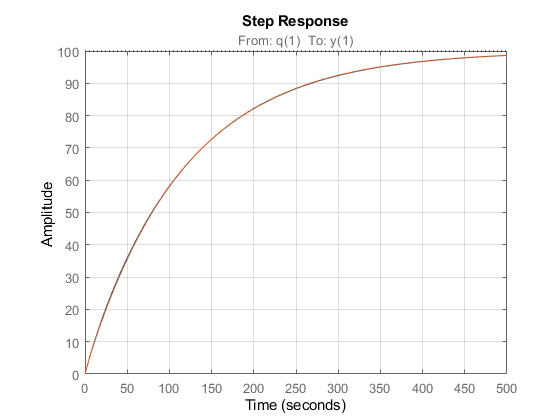


    % Look for poles with positive real parts
    if ~isempty(find(pole(G(:,:,i)) > 0, 1))
        disp('Unstable: Poles in the right hand plane.')
        disp(pole(G(:,:,i)))
        close(d)
        delete(fig)
        return
    end

    % Plot step response for temperature of air
    step(G(1,1,i), t); grid on; hold on

    y(:,i) = step(G(1,1,i), t);

    % Calculate the time constant for the T_a loop
    tau_T_a = find(abs(y(:,i) - y(end,i)) >= 0.37*y(end,i), 1, 'last') / 10

tau_T_a = 111.7000

tau_T_a = 112

end

if ~exist('C0','var')
    % Prepare a tunable controller to connect to above plant model
    decoupler = tunableGain('gain_block', eye(3));
    decoupler.InputName = 'e';
    decoupler.OutputName = 'p';

    PI_1 = tunablePID('PI_1', 'pi');
    PI_1.InputName = 'p(1)';
    PI_1.OutputName = 'q(1)';

    PI_2 = tunablePID('PI_2', 'pi');
    PI_2.InputName = 'p(2)';
    PI_2.OutputName = 'q(2)';

    PI_3 = tunablePID('PI_3', 'pi');
    PI_3.InputName = 'p(3)';
    PI_3.OutputName = 'q(3)';

    % Create a sum block to match the desired feedback architecture
    sum_block = sumblk('e = r - y', 3);

## Controller Architecture

The controller is designed with the following basic architecture, with increased dimensionality.

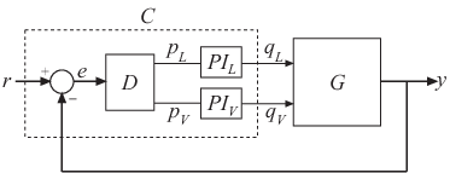

    % Connect all the components of the controller
    C0 = connect(PI_1, PI_2, PI_3, decoupler, sum_block, ...
        {'r','y'}, 'q');
end

% Select the number of optimization runs to conduct
runs = 6;
options = looptuneOptions('RandomStart', runs, ...
    'UseParallel', true);

The chosen loop bandwidth range was $\left\lbrack 10\;100\right\rbrack$ and, for the tracking requirement, a maximum percent error of 10% was selected.

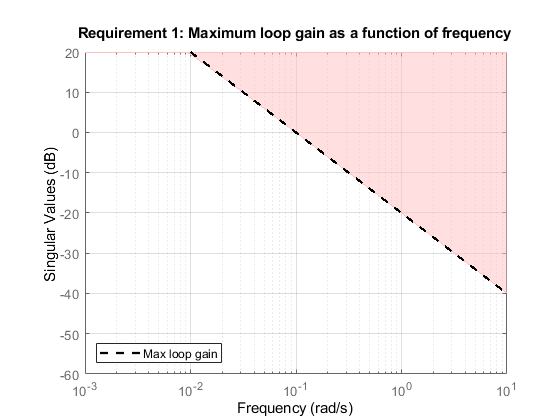

loop_bandwidth_range = [10, 100];
% max_error_percent = 0.10;
% tracking_requirement = TuningGoal.Tracking('r(1)', 'y(1)', ...
%     max_error_percent);

analysis_point_input = AnalysisPoint('q',3);
% Specify a max loop gain of 1 (log10(1) = 0 dB) at 1 rad/s, 0.1 at 10 rad/s and 1e-3 at 100 rad/s
max_controller_gain_requirement = TuningGoal.MaxLoopGain('q', frd([0.1 0.01 1e-3],[1 10 100]));
viewGoal(max_controller_gain_requirement)

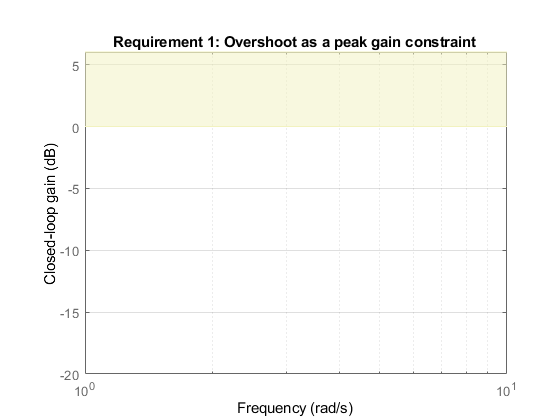


analysis_point_output = AnalysisPoint('y',3);
max_percent_overshoot = 5;
overshoot_requirement = TuningGoal.Overshoot('r', 'y', max_percent_overshoot);
viewGoal(overshoot_requirement)

Using the looptune function provided by the MathWorks Control System Toolbox, the controller that follows was tuned that meets these requirements.

- Bandwidth - Gain crossover for each loop falls within the frequency range

- Performance - Integral action at frequencies below the frequency range

- Robustness - Adequate stability margins and gain roll-off at frequencies above the frequency range

[P, C, gam, info] = looptune(G(:,:,1), C0, loop_bandwidth_range,... % options);
    max_controller_gain_requirement,...

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
Final: Peak gain = 9.87, Iterations = 91
Final: Peak gain = 20.3, Iterations = 96
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 90.5, Iterations = 95
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 9.87, Iterations = 139
Final: Peak gain = 9.9, Iterations = 142
Final: Peak gain = 9.9, Iterations = 59
Final: Peak gain = 9.88, Iterations = 167


    overshoot_requirement,...
    options);
% disp('Peak Gain < 1 indicates looptune was able to find parameter values that achieve the target loop bandwidth.')

% if gam <= 1
%     disp('All tuning requirements satisfied.')
% else
%     disp('At least 1 requirement is unmet.')
%     close(d)
%     delete(fig)
%     return
% end

PI_1 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 2.85, Ki = 0.375
 
Name: PI_1
Continuous-time PI controller in parallel form.
-----------------------------------
PI_2 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.0726, Ki = 0.0373
 
Name: PI_2
Continuous-time PI controller in parallel form.
-----------------------------------
PI_3 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 2.79, Ki = 5.2
 
Name: PI_3
Continuous-time PI controller in parallel form.
-----------------------------------
gain_block =
 
  D = 
               u1          u2          u3
   y1      0.3503   -0.003447   -0.002079
   y2      0.2957       1.981     -0.1377
   y3   2.928e-05  -2.346e-05     0.03283
 
Name: gain_block
Static gain.


ans =
 
  From input "q(1)" to output...
              0.9965 s + 0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
                   0.06643
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(2)" to output...
                   0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
               6.667 s + 0.1329
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(3)" to output...
                   0.06643 s + 0.004429
   y(1):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
                         0.004429
   y(2):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
          6.667
   y(3):  -----
          s + 1
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 2 3;2 2 3;0 0 1]   Number 

showTunable(C); % show the tuned controller parameters

P =
 
  From input "q(1)" to output...
              0.9965 s + 0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
                   0.06643
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(2)" to output...
                   0.06643
   y(1):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
               6.667 s + 0.1329
   y(2):  --------------------------
          s^2 + 0.0866 s + 0.0006643
 
   y(3):  0
 
  From input "q(3)" to output...
                   0.06643 s + 0.004429
   y(1):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
                         0.004429
   y(2):  ---------------------------------------
          s^3 + 1.087 s^2 + 0.08726 s + 0.0006643
 
          6.667
   y(3):  -----
          s + 1
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 2 3;2 2 3;0 0 1]   Number of

G(:,:,1)
P


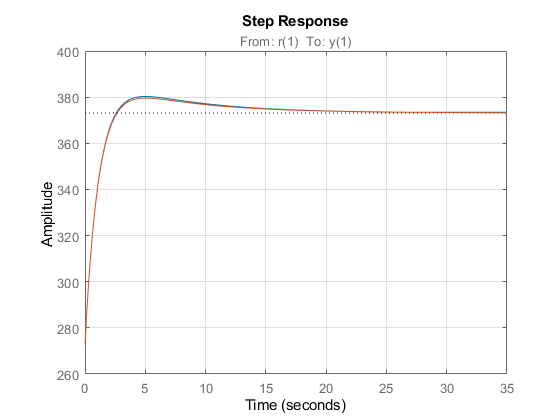

figure
C.Ts = 0;
for i = 1:2
    % Connect the controller and plant model in a feedback loop
    T(:,:,i) = connect(G(:,:,i), C, 'r', 'y');
    %T2 = connect(G(:,:,2), C, 'r', 'y');

    % Provide initial conditions
    step_options = stepDataOptions( ...
        'InputOffset', initial_conditions(1),...
        'StepAmplitude', temp_desired-initial_conditions(1));

    % Plot the step response

    step(T(1,1,i), step_options); grid on; hold on
end

% % Convert model to discrete time
% G_discrete = c2d(G, delta_t);
% G.InputName = 'q';
% C.Ts = delta_t;
% T_discrete = connect(G_discrete, C, 'r', 'y')
% figure
% step(T(1,1), '--', T_discrete(1,1), '-', step_options)
% axis([0 1 260 380])

% Save simulation results
% Close / Delete the progress dialog
close(d)
delete(fig)

try
    working_folder = pwd;
    dir_info = dir;
    make_folder = true;

    for i = 1:length(dir_info)
        if strcmpi(dir_info(i).name, 'arda_sim_results')
            make_folder = false;
            break
        end
    end

    if make_folder
        mkdir('arda_sim_results\')
    end

    datetime_str = datestr(now,'yyyy-mm-dd_HHMMSS');

    figure_filename = sprintf('step_response_%s.fig', ...
        datetime_str);
    savefig(fullfile(working_folder, 'arda_sim_results', ...
        figure_filename));
    close all

    variables_filename = sprintf('arda_sim_results_%s', ...
        datetime_str);
    save(fullfile(working_folder, 'arda_sim_results', ...
        variables_filename));

catch
    error('Unable to save simulation results.')
end

## Appendix

### Glossary and Acronyms

    **aRDA: **Advanced Research Drying Apparatus

    **freestream:** also referred to as upstream fluid velocity

    **RDA: **Research Drying Apparatus

    ** SBIR: **Small Business Innovation Research

    **USDA: **United States Department of Agriculture

    **Wet basis: **Refers to a particular method of measuring moisture content

    **equilibrium vapor pressure, **$p_s$**: **See saturation vapor pressure

    **enthalpy of condensation:** the energy required for a direct phase transition from gaseous to liquid state. Equal in quantity to and with opposite sign of the enthaply of vaporization.

    **enthalpy of vaporization: **$\Delta H_{\textrm{vap}}$ the energy required for a direct phase transition from liquid and gaseous state. 

    **heat of condensation:** See enthalpy of condensation.

    **heat of evaporation: **Equivalent to enthalpy of vaporization.

    **heat of vaporization: **$\Delta H_{\textrm{vap}}$. Equivalent to enthalpy of vaporization.

    **humidity ratio: **See specific humidity.

    **isobaric process: **A thermodynamic process in which the pressure remains constant. (Note: Isobaric expansion of a gas requires heat transfer to keep the pressure constant.)

    **isochoric process: **a thermodynamic process in which the volume remains constant. (Note: Here the system does no work. The only change is that the gas gains internal energy.)

    **latent heat of vaporization: **Equivalent to enthalpy of vaporization.

    **molar enthalpy of vaporization: **The same quantity as enthalpy of vaporization but stated in J/mol or kJ/mol.

    **mole fraction of water vapor, :** The mole fraction of water vapor is the ratio of the number of moles of water vapor in the moist air to the total number of moles of dry air and water vapor.

    **saturation vapor pressure (equilibrium vapor pressure), **$p_s$: The vapor pressure of a system, at a given temperature, for which the vapor of a substance is in equilibrium with a plane surface of that substances's pure liquid or solid phase; that is, the vapor pressure of a system that has attained saturation but not supersaturation.

    **specific heat of vaporization: **The same quantity as enthalpy of vaporization but stated in kJ/kg or J/g.

    **specific humidity, **$q$: (of an air sample) The ratio of the weight of water vapor contained in the sample compared to the weight of the dry air in the sample. (Also referred to as humidity ratio.)

    **vapor pressure, **$P_v$: The pressure exerted by the molecules of a given vapor. For a vapor mixed with other vapors or gases, it is that vapor's contribution to the total pressure (i.e. its partial pressure). Here, it denotes exclusively the partial pressure of water vapor in the systems contained air mass.